% Set our function
syms x
f(x) = (x^2 + 1)^(-1);

% Set inputs and outputs
inputs = linspace(-5, 5, 21);
a = f(inputs);
b = zeros(1, 20);
c = zeros(1, 21); % For Step 5&6. c(21) is not output.
d = zeros(1, 20);

% Step 1
h = inputs(2) - inputs(1);

% Step 2
alpha = zeros(1, 20);
for i = 2:20
    alpha(i) = 3/h*(a(i+1)-a(i)) - 3/h*(a(i)-a(i-1));
end

% Step 3
l = zeros(1, 21);
l(1) = 1;
mu = zeros(1, 21);
z = zeros(1, 21);

% Step 4
for i = 2:20
    l(i) = 4*h - h*mu(i-1);
    mu(i) = h/l(i);
    z(i) = (alpha(i) - h*z(i-1)) / l(i);
end

% Step 5
l(21) = 1;
z(21) = 0; % actually z = zeros(1, 21) already implies this
c(21) = 0; % actually c = zeros(1, 21) already implies this

% Step 6
for j = 20:-1:1
    c(j) = z(j) - mu(j)*c(j+1);
    b(j) = (a(j+1) - a(j)) / h - h * (c(j+1) + 2*c(j)) / 3;
    d(j) = (c(j+1) - c(j)) / (3*h);
end

% Step 7: Plotting
X = linspace(-5, 5, 51)

X =    -5.0000   -4.8000   -4.6000   -4.4000   -4.2000   -4.0000   -3.8000   -3.6000   -3.4000   -3.2000   -3.0000   -2.8000   -2.6000   -2.4000   -2.2000   -2.0000   -1.8000   -1.6000   -1.4000   -1.2000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000


Y = zeros(1, 51);

S(x) = a(1) + b(1)*(x-inputs(1)) + c(1)*(x-inputs(1))^2 + d(1)*(x-inputs(1))^3;
j = 1;
for i = 1:51
    if inputs(j+1) < X(i)
        j = j + 1;
        S(x) = a(j) + b(j)*(x-inputs(j)) + c(j)*(x-inputs(j))^2 + d(j)*(x-inputs(j))^3;
    end
    Y(i) = S(X(i)) - f(X(i));
end
disp(Y);

         0    0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0001    0.0001   -0.0003   -0.0009   -0.0000    0.0029    0.0019   -0.0015   -0.0021    0.0000   -0.0021   -0.0015    0.0019    0.0029   -0.0000   -0.0009   -0.0003    0.0001    0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001   -0.0000



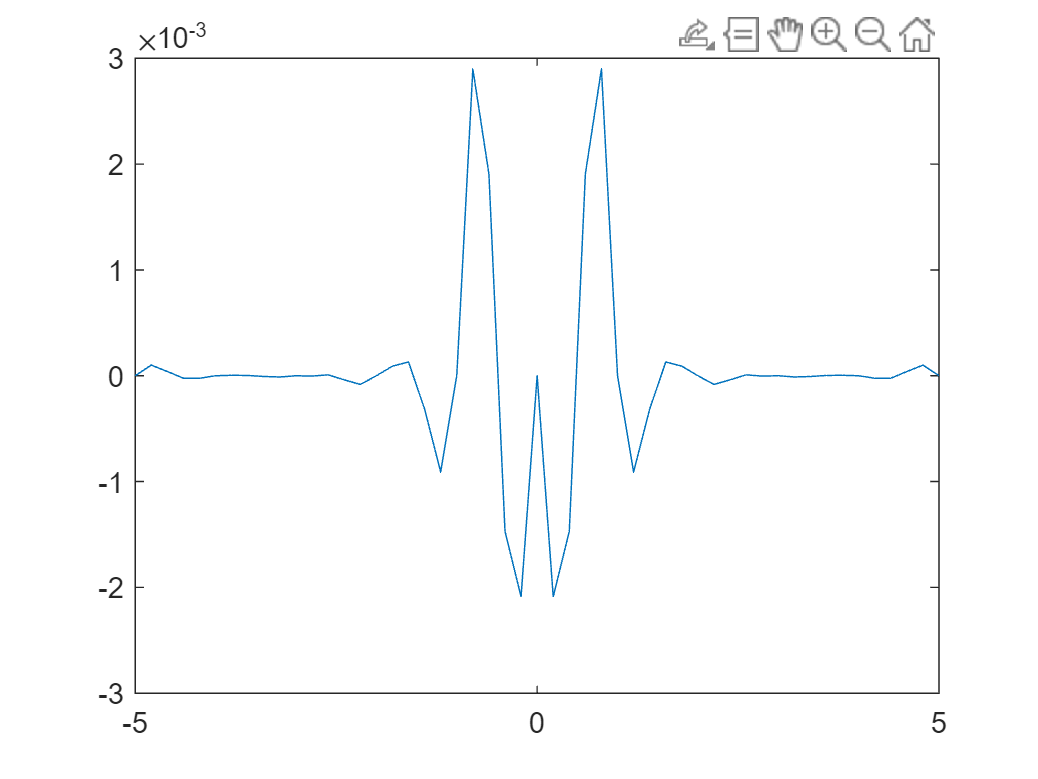

plot(X, Y);